# arrow

Add an arrow annotation to a plot

`arrow(start,end)` adds an arrow to the current axes from the (*x*,*y*) point defined by the 2-element vector `start` to the (*x*,*y*) point defined by the 2-element vector `end`.

`arrow(ax,start,end)` adds an arrow to the axes `ax`.

`arrow(...,str)` uses the line style specification string `str` to set the color and line style of the arrow. The string can be any line style specification string that is accepted by `plot` (e.g. `'k:'`, `'m-*'`, etc.). However, markers are ignored.

`arrow(...,name,value)` formats the arrow with additional options specified by one or more Name,Value pair arguments. Available options are:

`'Color'       `Color of the arrow (line and arrowhead)

              String or 1-by-3 RGB vector

              Default: `'k'` ([0 0 0])

`'HeadLength'  `Length of the arrowhead in pts (1/72 inch)

              Positive numeric scalar

              Default: 10

`'HeadWidth'   `Width of the arrowhead in pts (1/72 inch)

              Positive numeric scalar

              Default: 10

Note that `HeadLength` is scaled if necessary to be no more than half the length of the arrow. `HeadWidth` is scaled equivalently, to maintain the aspect ratio.

`'HeadIndent'  `Amount of indentation of the back of the arrowhead

              Numeric scalar between -1 and 1

              Default: 0.2

`'LineStyle'   `Style of arrow line

              String (any line style string accepted by `plot`)

              Default: `'-'`

`'LineWidth'   `Width of arrow line, in pts (1/72 inch)

              Positive numeric scalar

              Default: 0.5

`a = arrow(...)` returns a graphics object group `a` containing the graphics objects of the arrow.

Examples

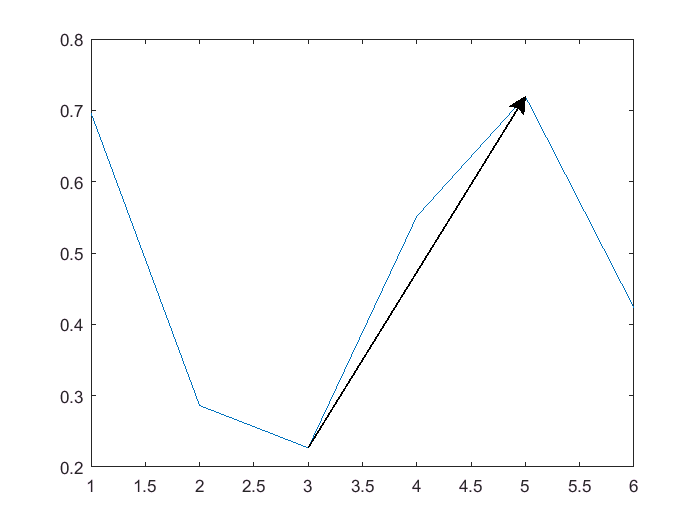

rng(123)
x = rand(1,6);
plot(x)
arrow([3 x(3)],[5 x(5)])

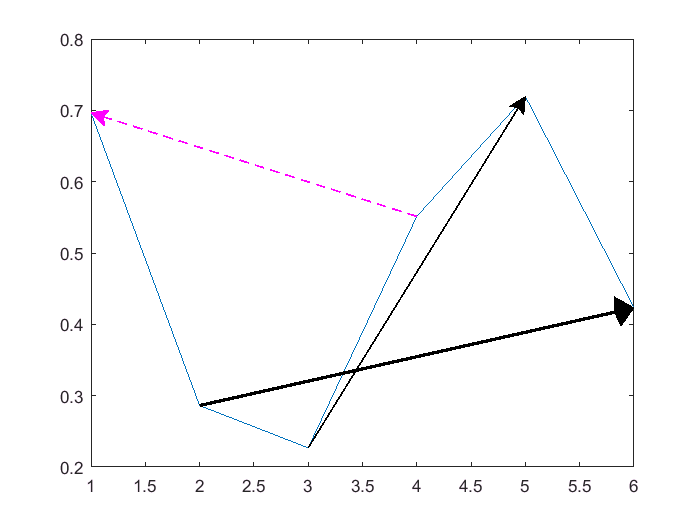

arrow([4 x(4)],[1 x(1)],'m--')
arrow([2 x(2)],[6 x(6)],'r','Linewidth',2,'HeadIndent',-0.2,'HeadWidth',18)